%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI 

% This MATLAB script reads CIR (Channel Impulse Response) data from text files,
% processes it, and visualizes both the magnitude and phase of the CIRs.
% The user is prompted to specify the number of CIRs to display, and the script
% handles data extraction, magnitude calculation, and envelope plotting.
% Read files and extract data

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file_paths = {'location(7,1)_responder1.txt'};
all_CIR_real_all = {};
all_CIR_imag_all = {};

% Loop through each file and read CIR values
for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurments(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end

Total number of read CIR pairs for location(7,1)_responder1.txt: 1030


disp(['==========================================================================']);               

CIR number 1 for location(7,1)_responder1.txt


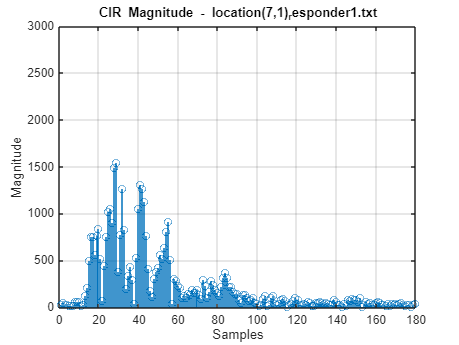

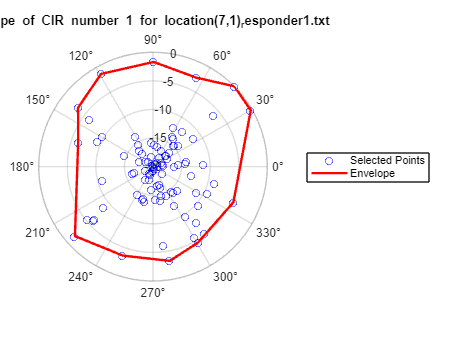

CIR number 2 for location(7,1)_responder1.txt


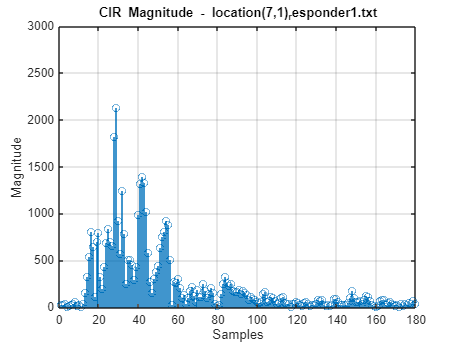

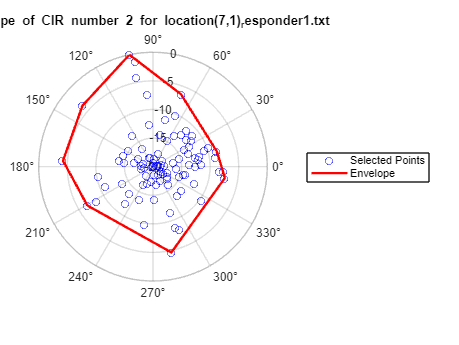

CIR number 3 for location(7,1)_responder1.txt


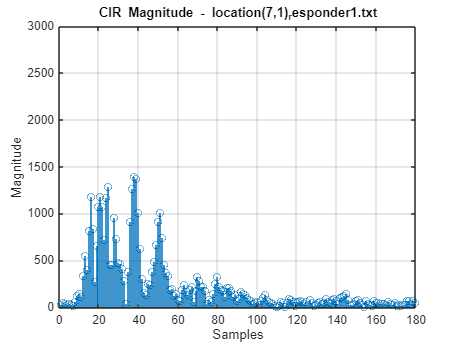

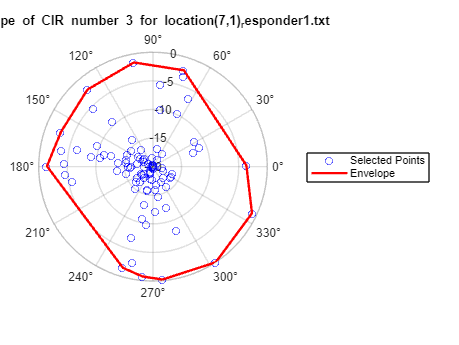

CIR number 4 for location(7,1)_responder1.txt


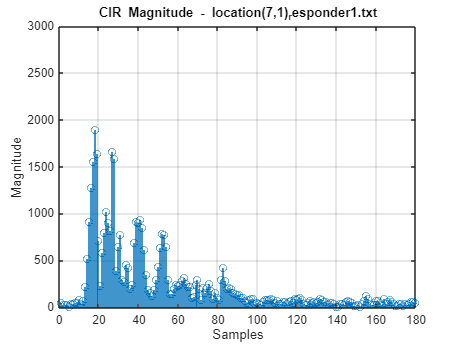

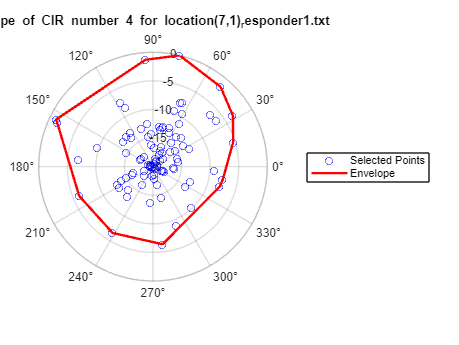

CIR number 5 for location(7,1)_responder1.txt


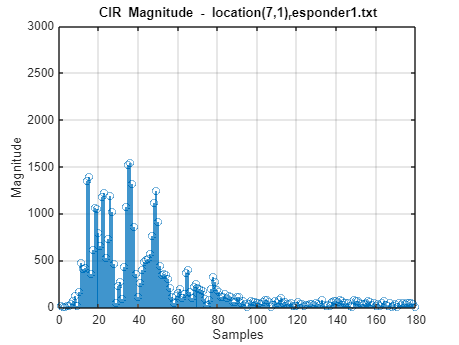

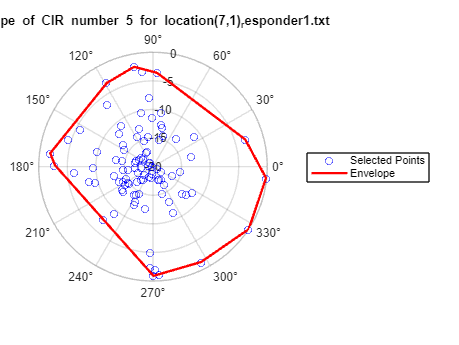

CIR number 6 for location(7,1)_responder1.txt


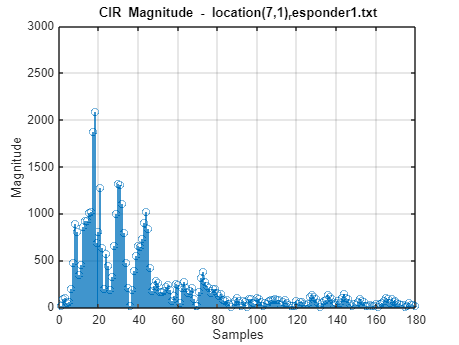

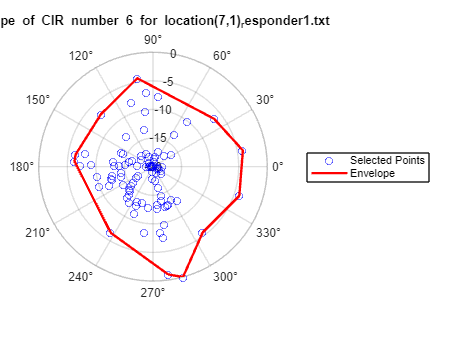

CIR number 7 for location(7,1)_responder1.txt


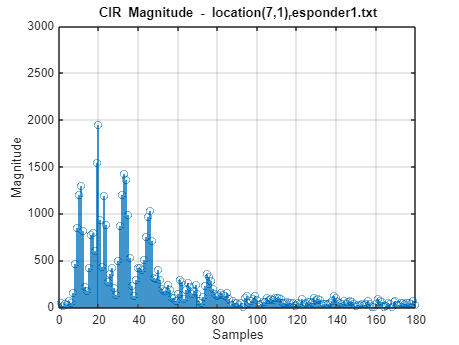

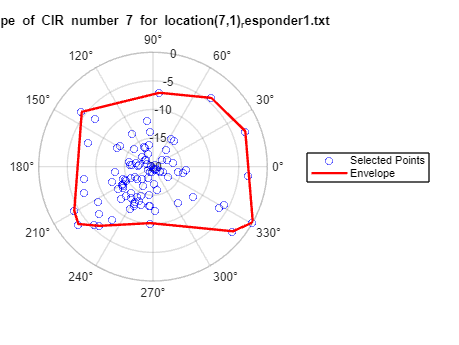

CIR number 8 for location(7,1)_responder1.txt


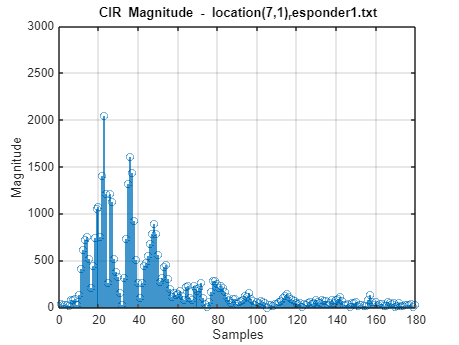

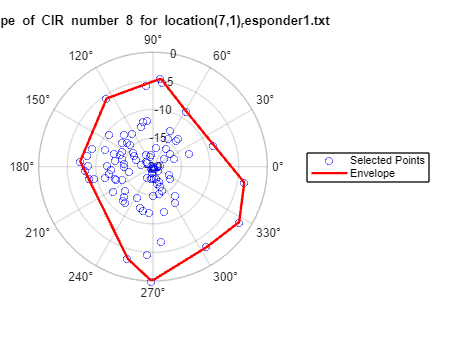

CIR number 9 for location(7,1)_responder1.txt


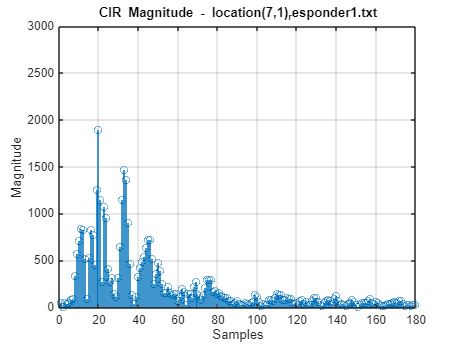

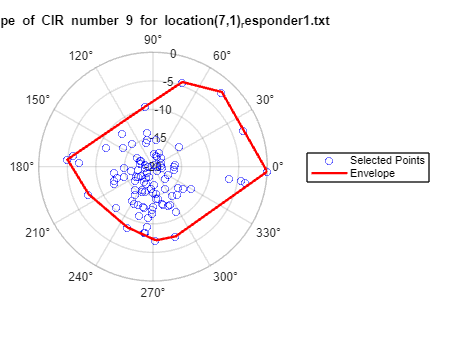

CIR number 10 for location(7,1)_responder1.txt


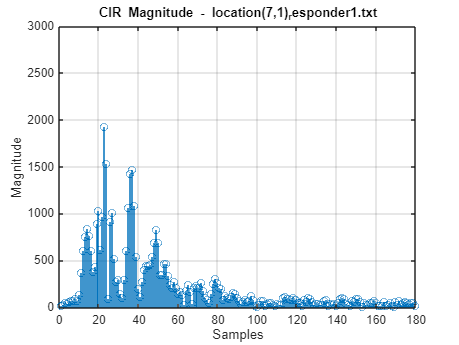

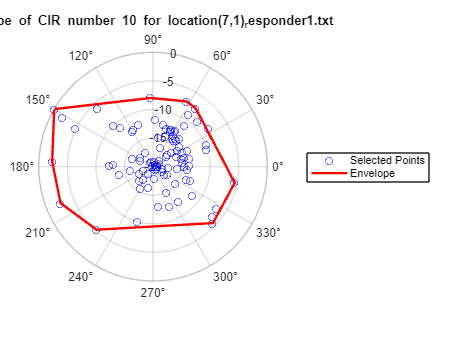


while true
    % Prompt the user for the number of CIRs to display
    prompt = 'Enter the number of CIRs you want to display or 0 to exit: ';
    numCIRs = input(prompt);
    
    if numCIRs == 0 % Exit if 0 is pressed
        break;
    end
    
    if numCIRs > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end
    
    for CIRNumber = 1:numCIRs
        for i = 1:length(file_paths)
            file_path = file_paths{i};
            CIR_real_all = all_CIR_real_all{i};
            CIR_imag_all = all_CIR_imag_all{i};

            if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
                disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
                disp(['==========================================================================']);               

                % Work with samples between 730 and the end
                CIR_real = CIR_real_all{CIRNumber}(730:end)';
                CIR_imag = CIR_imag_all{CIRNumber}(730:end)';
                CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);

                % Display the CIR magnitude
                figure;
                stem(CIR_magnitude);
                title(['CIR Magnitude - ', file_path]);
                xlabel('Samples');
                ylabel('Magnitude');
                axis([0 180 0 3000]);
                grid on;

                % Sort indices by descending magnitude
                [~, sortedIdx] = sort(CIR_magnitude, 'descend');

                % Select a larger set of points based on CIR magnitude
                numPoints = min(100, length(sortedIdx)); % Select the 100 largest magnitudes or fewer if not enough points
                selectedIdx = sortedIdx(1:numPoints); 
                selectedReal = CIR_real(selectedIdx);
                selectedImag = CIR_imag(selectedIdx);
        
                % Ensure selectedReal and selectedImag are column vectors
                if isrow(selectedReal)
                    selectedReal = selectedReal';
                end
                if isrow(selectedImag)
                    selectedImag = selectedImag';
                end
        
                % Use boundary to calculate the envelope
                k = boundary(selectedReal, selectedImag, 0.2); % Adjust the shrink factor to get a looser or tighter envelope
        
                % Convert real and imaginary values to phase in degrees
                CIR_phase = rad2deg(atan2(selectedImag, selectedReal));
        
                % Normalize magnitudes before converting to dB
                maxMagnitude = max(CIR_magnitude(selectedIdx));
                magnitudes_dB = 20 * log10(CIR_magnitude(selectedIdx) / maxMagnitude);
        
                % Display the envelope on the polar plot
                figure;
                polarplot(deg2rad(CIR_phase), magnitudes_dB, 'bo');
                hold on;
                polarplot(deg2rad(CIR_phase(k)), magnitudes_dB(k), 'r-', 'LineWidth', 2);
        
                % Set limits and spacing for the radial axis in dB
                rlim([-20 0]); % Radial axis limits
                rticks([-20 -15 -10 -5 0]); % Tick spacing
                title(['Shape of CIR number ', num2str(CIRNumber), ' for ', file_path]);
                legend('Selected Points', 'Envelope');
                hold off;
            end

            disp(['==========================================================================']);               
        end
    end
end